clc; close all; clearvars;

load('mats/ifiss.mat');

tau = 1e-1;
M = G + tau * Ast;
A = tau * Bst';
C = C + 1e-10*speye(size(C));
N = tau * C;

[m, n] = size(A);

dM = decomposition(M, 'chol');
dN = decomposition(N, 'chol');
Mfunc = @(x, t) Mopertor(M, dM, x, t);
Nfunc = @(x, t) Mopertor(N, dN, x, t);

b = tau * fst;
c = tau * gst;
x = zeros(m, 1);

exres = true;
show_info = true;
tol = 1e-10;

stol = 1e-10;
k = 100;
p = 200;
maxcycle = 10;
maxit = 2000;

resvec1 = [];
resvec2 = [];
num_rhs = 10;

for i = 1:num_rhs
    rx = b + G * x;
    ry = c;
    [x, ~, ~, resvec] = tricg(A, rx, ry, Mfunc, Nfunc, tol, maxit, exres=exres, show_info=show_info);
    resvec1 = [resvec1; resvec];
end

x = zeros(m, 1);

rx = b + G * x;
ry = c;
[x, y, ~, resvec, U, T, V, MU, NV] = tricgdr_two_stage(A, rx, ry, Mfunc, Nfunc, [k, 0], p, tol, ...
                          maxcycle, maxit=maxit, stol=stol, exres=exres, show_info=show_info);

singular triplets converge at 3th cycle, absolute residual = 3.967214e-15, and relative residual = 1.298557e-17.


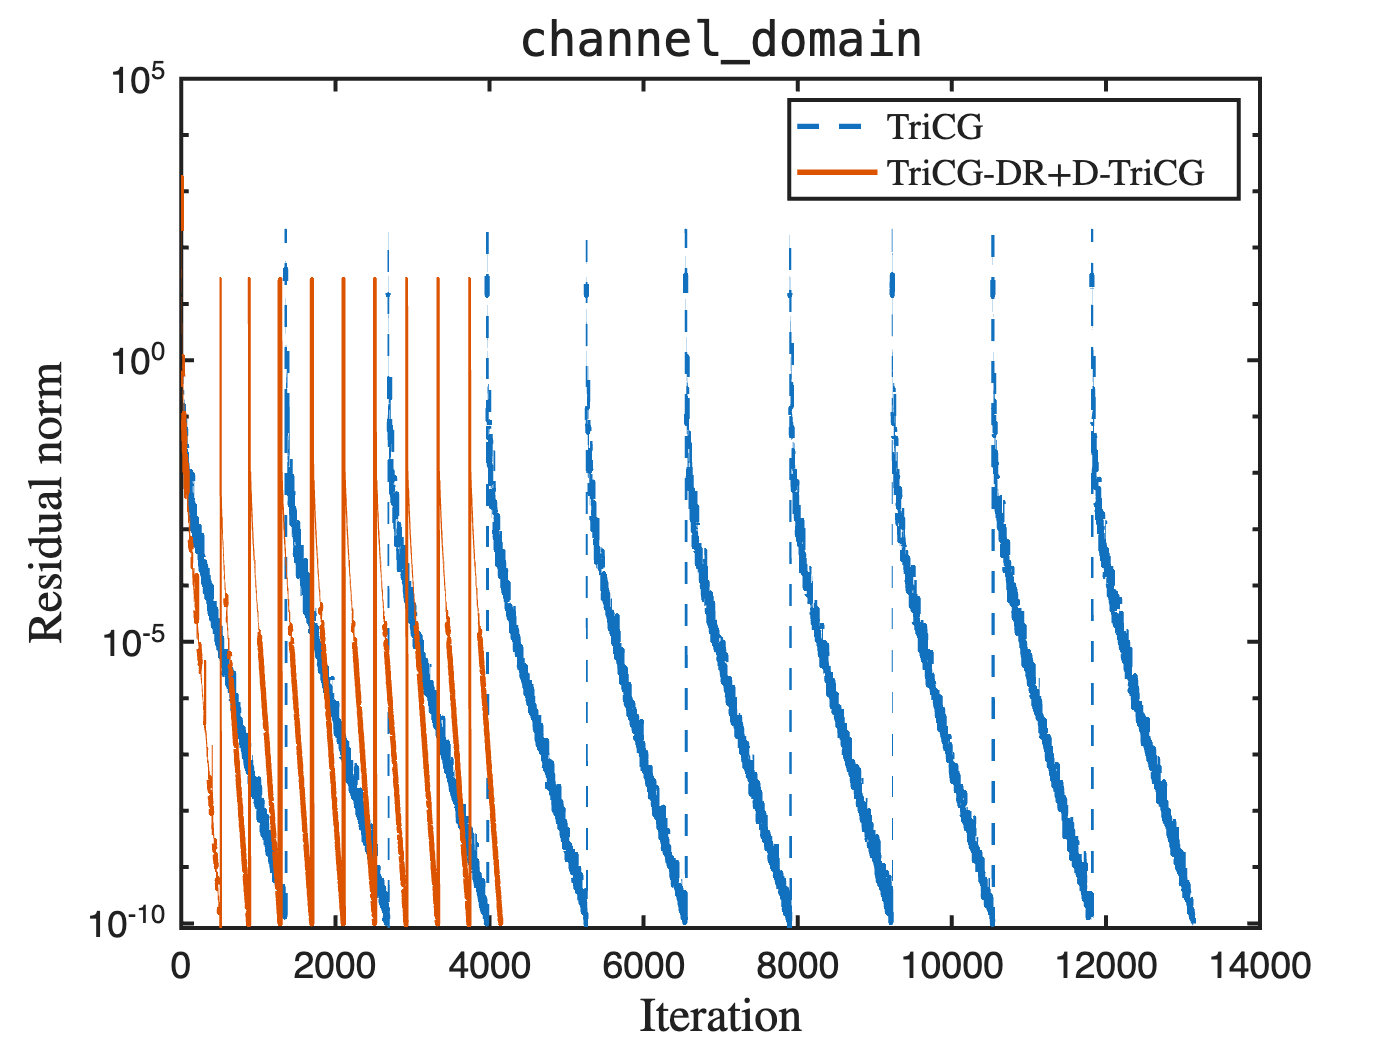

resvec2 = [resvec2; resvec];

for i = 2:num_rhs
    rx = b + G * x;
    ry = c;
    rx = rx - MU * (U'*rx);
    ry = ry - NV * (V'*ry);

    [x, y, ~, resvec] = tricg(A, rx, ry, Mfunc, Nfunc, tol, maxit, exres=exres, show_info=show_info, ...
        augU=U, augMU=MU, augV=V, augNV=NV);
    resvec2 = [resvec2; resvec];
end

default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
    'defaultLineLineWidth'};

default_vals = {14, 1.5, 2};
set(0, default_properties, default_vals);

figure(Position=[180 120 800 600]);

semilogy(0:length(resvec1)-1, resvec1, LineStyle='--');
hold on;
semilogy(0:length(resvec2)-1, resvec2, LineStyle='-');
hold off;

title('\texttt{channel\_domain}', Interpreter='latex', FontSize=18);
xlabel('Iteration', Interpreter='latex', FontSize=18);
ylabel('Residual norm', Interpreter='latex', FontSize=18);
legend({'TriCG', 'TriCG-DR+D-TriCG$\ $'}, Location='northeast', ...
    Interpreter='latex', FontSize=14);

% exportgraphics(gcf, 'figs/fig4.pdf', Resolution=600);